初版：2022年1月15日

# シミュレーション　講義ノート No.7

#### 藤原　哉

#### 農林中央金庫

### 1. デフォルトを考慮した価格評価

デフォルトを考慮した価格評価ではデフォルト時刻の分布が指数分布に従うとする「誘導型モデル」が用いられることが多い。誘導型モデルではデフォルト強度を $\lambda(t)$とする。時刻 $t$まで生存する確率を $\mathbb{P}^{{\rm surv}}(t)$とすると $[t,t+dt]$でデフォルトする確率は $\lambda(t) dt$であるので


$$\mathbb{P}^{{\rm surv}}(t+dt) = (1-\lambda(t) dt) \mathbb{P}^{{\rm surv}}(t) \\ \frac{\mathbb{P}^{{\rm surv}}(t+dt)-\mathbb{P}^{{\rm surv}}(t)}{dt} = -\lambda(t)$$
 

となる。イメージを下に示す。

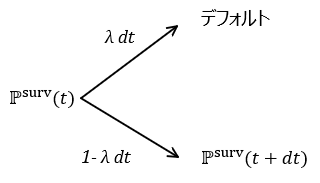

時点 $t=0$では生存確率は $1$であるので微分方程式の解は


$$\mathbb{P}^{{\rm surv}}(t) = {\rm e}^{-\int_0^t \lambda(s) {\rm d}s}$$


となる。 $\lambda(t)$が確率過程である場合を考慮すると


$$\mathbb{P}^{{\rm surv}}(t) = \mathbb{E}\left[{\rm e}^{-\int_0^t \lambda(s) {\rm d}s} \right]$$


と表される。時刻tまで生存し微小区間 $[t,t+{\rm d} t]$でデフォルトする確率は $\lambda {\rm d} t \times \mathbb{P}^{surv}(t)$ である。

時点 $t$でデフォルトしたときの清算価値が $P(t)$,満期 $T$までデフォルトがないときは$P(T)$で償還される金融商品を商品があるとする。簡単のためにキャッシュフローは満期だけで発生する商品とする。

このとき金融商品の発行体のデフォルト強度を $\lambda(t)$、回収率を $R(t)$とすと、デフォルトを考慮した金融商品の価格 $D(t)$は


$$D(t) = \mathbb{E}_t^{\mathbb{Q}} \left[ \int_t^T {\rm e}^{-\int_{t}^{s} r(u) {\rm d} u} R(s) P(s) \lambda(s) {\rm e}^{-\int_t^s \lambda(u) {\rm d} u } {\rm d} s + P(T) {\rm e}^{-\int_t^T \lambda(s) {\rm d} s} {\rm e}^{-\int_t^T r(s) {\rm d} s}\right]$$


となる。  以降は計算を簡単にするために 回収率とデフォルト強度は定数（$R(s) = R$, $\lambda(s) = \lambda$）とする。

このときの金融商品の価格は


$$D(t) = R\lambda \mathbb{E}_t^{\mathbb{Q}} \left[ \int_t^T {\rm e}^{-\int_t^s r(u){\rm d}u} P(s)  {\rm e}^{-\lambda(s-t)} {\rm d} s \right]+ {\rm e}^{-\lambda (T-t)} \mathbb{E}_t^{\mathbb{Q}} \left[ P(T) {\rm e}^{-\int_t^T r(u) {\rm d} u} \right]$$


となる。デフォルト時の清算価格 $P(t)$と短期金利 $r_t$の確率過程が与えられるとシミュレーションによりデフォルトリスクを考慮した価格評価を行うことができる。

なお、デフォルト時の清算価格 $P(t)$のモデル化には次のような考え方がある。

- 額面を基準にして清算する。債券やローンなど償還元本がある商品が対象。

- デフォルトリスクを考慮しない時価を基準にして清算する。オプションやスワップなど償還元本がないデリバティブが対象。

- デフォルトリスクを考慮した時価で清算する。オプションやスワップなど償還元本がないデリバティブが対象。

清算価格の評価方法は契約・慣行に基づいて実際の清算に近い方式に応じて選択することになる。

### 例：割引債価格

満期 $T$の割引債のデフォルトを考慮した価格評価を例として考える。元本を1とすると $P(T) = 1$である。割引債価格の原資産(状態変数）は短期金利とする。

以下では、短期金利 $r_t$はVasicekモデルに従うとする。


$${\rm d} r_t = \left(\theta - \kappa r_t \right) {\rm d} t + \sigma {\rm d}W_t$$


ただし、 $\theta, \kappa, \sigma$は定数とする。

Vasicekモデルには解析解が存在し、 $r_t$を所与とすると


$${\rm r}_{t+\Delta t} = r_t {\rm e}^{-\kappa \Delta t} + \frac{\theta}{\kappa} \left( 1 - {\rm e}^{-\kappa \Delta t} \right) + \sigma {\rm e^{-\kappa (t+\Delta t)} \int_{t}^{t+\Delta t} {\rm e}^{\kappa s} {\rm d}W_s$$


と表される。また、デフォルトリスクがないときの割引債価格の解析解も存在し


$$DF(t,T) = \mathbb{E}_t \left[ {\rm e}^{-\int_t^T r_s {\rm d}s } \right] = A(t,T) {\rm e}^{-B(t,T) r_t} \\ A(t,T) = {\rm e}^{-\frac{\theta}{\kappa}\left[T-t - \frac{1-{\rm e}^{-\kappa(T-t)}}{\kappa}\right] + \frac{\sigma^2}{2\kappa^2} \left[T-t - 2 \frac{1-{\rm e}^{-\kappa(T-t)}}{\kappa} + \frac{1-{\rm e}^{-2\kappa(T-t)}}{2\kappa}\right] \\ B(t,T) = \frac{1-{\rm e}^{-\kappa (T-t)}}{\kappa}$$


となる。ただし、 $DF(t,T)$は時点 $t$での満期Tの割引債価格である。

割引債の発行体のデフォルト強度を $\lambda$、デフォルト時の回収率を $R$として、デフォルトを考慮した割引債価格を評価する。

**額面清算の場合**

債券の場合は額面清算とすることが自然である。この場合のデフォルトリスクを考慮した割引債価格 $D(t,T)$は $P(t)=1$であるので


$$D(t,T) = R\lambda  \mathbb{E}_t^{\mathbb{Q}} \left[ \int_t^T {\rm e}^{-\int_t^s r(u){\rm d}u}  {\rm e}^{-\lambda(s-t)} {\rm d} s \right]+ {\rm e}^{-\lambda (T-t)} \mathbb{E}_t^{\mathbb{Q}} \left[ {\rm e}^{-\int_t^T r(u) {\rm d} u} \right]$$


となる。短期金利 $r_t$を離散近似によりシミュレーションで評価することができる。

また、Vasicekモデルでの割引債価格の解析解を用いると


$$D(t,T) = R \lambda \int_t^T \mathbb{E}_t^{\mathbb{Q}} \left[{\rm e}^{-\int_t^s r_u {\rm d}u} \right] {\rm e}^{-\lambda(s-t)} {\rm d}s  +A(t,T) {\rm e}^{-B(t,T)r_t-\lambda (T-t) } \\  = R \lambda  \int_t^T A(t,s) {\rm e}^{-B(t,s) r_t} {\rm e}^{-\lambda(s-t)} {\rm d}s + A(t,T) {\rm e}^{-B(t,T) r_t-\lambda (T-t)}$$


となり、数値積分で求めることができる。

**実装例**

割引債の満期を10年とし, Vasicekモデルのパラメータは $r_0 =0, \theta = 0.01, \kappa = 0.1, \sigma = 0.005$、デフォルト強度は $\lambda = 0.01$、回収率は $0.4$とする。

短期金利の時間発展はVasicekモデルの解析解を用いる。


$${\rm r}_{t+\Delta t} = r_t {\rm e}^{-\kappa \Delta t} + \frac{\theta}{\kappa} \left( 1 - {\rm e}^{-\kappa \Delta t} \right) + \sigma {\rm e^{-\kappa (t+\Delta t)} \int_{t}^{t+\Delta t} {\rm e}^{\kappa s} {\rm d}W_s$$


ただし、 ${\rm Var}\left[\sigma {\rm e}^{-\kappa(t+\Delta t)} \int_t^{t+\Delta t} {\rm e}^{\kappa s} {\rm d}W_s \right] = \frac{\sigma^2}{2\kappa} \left(1- {\rm e}^{-2\kappa \Delta t} \right)$であることから、$\sigma {\rm e^{-\kappa (t+\Delta t)} \int_{t}^{t+\Delta t} {\rm e}^{\kappa s} {\rm d}W_s$は平均０、分散 $\frac{\sigma^2}{2\kappa} \left(1- {\rm e}^{-2\kappa \Delta t} \right)$の正規分布に従うことになる。よって、シミュレーションでは次のように実装する。


$${\rm r}_{t+\Delta t} = r_t {\rm e}^{-\kappa \Delta t} + \frac{\theta}{\kappa} \left( 1 - {\rm e}^{-\kappa \Delta t} \right) + \sqrt{ \frac{\sigma^2}{2\kappa} \left(1- {\rm e}^{-2\kappa \Delta t} \right)} \varepsilon \\ \varepsilon \sim N(0,1)$$


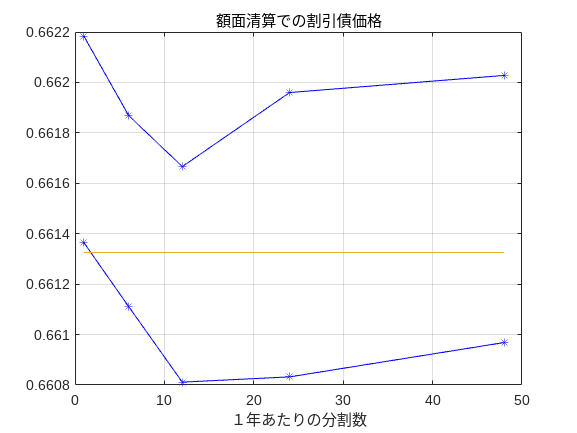

clear; 
% Vasicek model パラメータ
t0 = 0.0;
r0 = 0.0;
tht = 0.01; 
kappa = 0.1; 
sig = 0.005; 

% デフォルト関連パラメータ
lamb = 0.01;
rec = 0.4; 

% 満期
T = 10.0;

% デフォルトを考慮しない割引債価格
dfFun = @(rt,t,T) calcVasicekDF(rt,t,T,tht,kappa,sig);

% 数値積分での評価
% 被積分関数
intfun = @(s) dfFun(r0,t0,s).*exp(-lamb*(s-t0));
%数値積分解
dfni = rec*lamb*integral(intfun,t0,T) + exp(-lamb*(T-t0))*dfFun(r0,t0,T);

%シミュレーションでの評価
Nsim = 10000;
Nsteps = [1;6;12;24;48]; %　1年あたりの分割数

Nt = 10;
alp = 0.01;
lowers = zeros(size(Nsteps));
uppers = zeros(size(Nsteps));

for iloop = 1:size(Nsteps,1)
    Nstep = Nsteps(iloop);
    dt = 1/Nstep; 
    % dt stepでの標準偏差
    sigv = sig*sqrt((1-exp(-2*kappa*dt))/(2*kappa));
    vs = zeros(Nt,1);
    for jloop = 1:Nt
        % dt stepでの増分 (T-t0)/dtはステップ数
        sigdw = sigv * randn(Nsim,(T-t0)/dt);
        % 金利パスの生成
        rs = zeros(Nsim,(T-t0)/dt+1);
        rs(:,1) = r0;
        for kloop = 1:(T-t0)/dt
            rs(:,kloop+1) = rs(:,kloop)*exp(-kappa*dt) + tht/kappa*(1-exp(-kappa*dt)) + sigdw(:,kloop);
        end
        % 金利の積分近似（累積値）
        intr = cumtrapz((t0:dt:T),rs,2);
        % 被積分関数の時間グリッドでの値
        tmpf = exp(-intr - lamb*((t0:dt:T)-t0));
        % 数値積分
        vs(jloop) = mean(rec*lamb*trapz((t0:dt:T),tmpf,2) + exp(-lamb*(T-t0)-intr(:,end)));
    end
    rst = estConfidenceInterval(vs,alp);
    lowers(iloop) = rst.CILower;
    uppers(iloop) = rst.CIUpper;
end
nfig = 1;
figure(nfig);plot(Nsteps,[lowers,uppers],'b*-');grid; hold on; xlabel('１年あたりの分割数'); title('額面清算での割引債価格');
plot(Nsteps,dfni*ones(size(Nsteps)),'-');hold off;

**デフォルトを考慮しない時価での清算の場合**

デフォルトを考慮しない時価での清算の場合は $P(t) = DF(t,T)$となる。よって、デフォルトリスクを考慮した割引債価格 $D(t,T)$は


$$D(t,T) = R\lambda  \mathbb{E}_t^{\mathbb{Q}} \left[ \int_t^T {\rm e}^{-\int_t^s r(u){\rm d}u}  DF(r_s, s,T) {\rm e}^{-\lambda(s-t)} {\rm d} s \right]+ {\rm e}^{-\lambda (T-t)} \mathbb{E}_t^{\mathbb{Q}} \left[ {\rm e}^{-\int_t^T r(u) {\rm d} u} \right]$$


となる。一般には将来時点での状態において $DF(r_s,s,T)$を計算しなければならないので$DF(r_s,s,T)$に解析解がない場合には実装上の工夫が必要となる。

なお、割引債価格の場合には次のように解析解を得ることができる。ただし、 $L = 1-R$は損失率である。


$$D(t,T) = R \lambda \int_t^T \mathbb{E}_t^{\mathbb{Q}} \left[{\rm e}^{-\int_t^s r(u) {\rm d}u} \mathbb{E}_s^{\mathbb{Q}} \left[ {\rm e}^{-\int_s^T r(u) {\rm d}u}\right] \right] {\rm e}^{-\lambda(s-t)} {\rm d} s + {\rm e}^{-\lambda (T-t)} \mathbb{E}_t^{\mathbb{Q}} \left[{\rm e}^{-\int_t^T r(u) {\rm d} u} \right] \\ = R \lambda \mathbb{E}_t^{\mathbb{Q}} \left[{\rm e}^{-\int_t^T r(u) {\rm d}u}  \right]\int_t^T  {\rm e}^{-\lambda(s-t)} {\rm d} s + {\rm e}^{-\lambda (T-t)} \mathbb{E}_t^{\mathbb{Q}} \left[{\rm e}^{-\int_t^T r(u) {\rm d} u} \right] \\ = DF(t,T) \left( 1 -L\left( 1- {\rm e}^{-\lambda (T-t) }\right) \right)$$


**実装例**

額面清算での例と同じ設定での実装する。

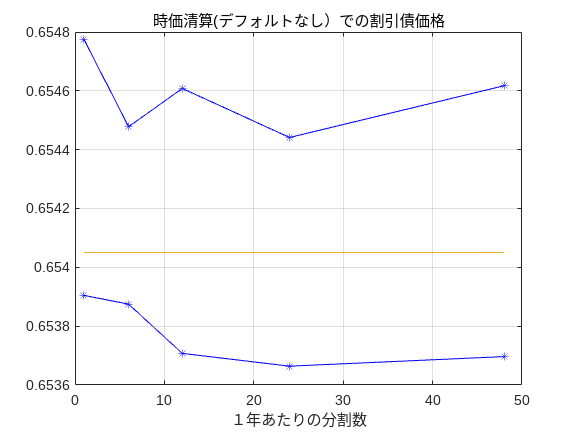

clear; 
% Vasicek model パラメータ
t0 = 0.0;
r0 = 0.0;
tht = 0.01; 
kappa = 0.1; 
sig = 0.005; 

% デフォルト関連パラメータ
lamb = 0.01;
rec = 0.4; 

% 満期
T = 10.0;

% デフォルトを考慮しない割引債価格
dfFun = @(rt,t,T) calcVasicekDF(rt,t,T,tht,kappa,sig);

% 解析解での評価
vana = dfFun(r0,t0,T).*(1-(1-rec)*(1-exp(-lamb*(T-t0))));

%シミュレーションでの評価
Nsim = 10000;
Nsteps = [1;6;12;24;48]; %　1年あたりの分割数

Nt = 10;
alp = 0.01;
lowers = zeros(size(Nsteps));
uppers = zeros(size(Nsteps));

for iloop = 1:size(Nsteps,1)
    Nstep = Nsteps(iloop);
    dt = 1/Nstep; 
    % dt stepでの標準偏差
    sigv = sig*sqrt((1-exp(-2*kappa*dt))/(2*kappa));
    vs = zeros(Nt,1);
    for jloop = 1:Nt
        % dt stepでの増分 (T-t0)/dtはステップ数
        sigdw = sigv * randn(Nsim,(T-t0)/dt);
        % 金利パスの生成
        rs = zeros(Nsim,(T-t0)/dt+1);
        dfs = zeros(Nsim,(T-t0)/dt+1);
        rs(:,1) = r0;
        dfs(:,1) = dfFun(rs(:,1),t0,T);
        for kloop = 1:(T-t0)/dt
            rs(:,kloop+1) = rs(:,kloop)*exp(-kappa*dt) + tht/kappa*(1-exp(-kappa*dt)) + sigdw(:,kloop);
            % 各時点での清算価値
            dfs(:,kloop+1) = dfFun(rs(:,kloop+1),t0+kloop*dt,T);
        end
        % 金利の積分近似（累積値）
        intr = cumtrapz((t0:dt:T),rs,2);
        % 被積分関数の時間グリッドでの値
        tmpf = exp(-intr - lamb*((t0:dt:T)-t0)).*dfs;
        % 数値積分
        vs(jloop) = mean(rec*lamb*trapz((t0:dt:T),tmpf,2) + exp(-lamb*(T-t0)-intr(:,end)));
    end
    rst = estConfidenceInterval(vs,alp);
    lowers(iloop) = rst.CILower;
    uppers(iloop) = rst.CIUpper;
end
nfig = 2;
figure(nfig);plot(Nsteps,[lowers,uppers],'b*-');grid; hold on; xlabel('１年あたりの分割数'); title('時価清算(デフォルトなし）での割引債価格');
plot(Nsteps,vana*ones(size(Nsteps)),'-');hold off;

**デフォルトを考慮する時価での清算の場合**

デフォルトを考慮する時価での清算の場合は $P(t) = D(t,T)$となる。よって、デフォルトリスクを考慮した割引債価格 $D(t,T)$は


$$D(t,T) = R\lambda  \mathbb{E}_t^{\mathbb{Q}} \left[ \int_t^T {\rm e}^{-\int_t^s r(u){\rm d}u}  D(r_s, s,T) {\rm e}^{-\lambda(s-t)} {\rm d} s \right]+ {\rm e}^{-\lambda (T-t)} \mathbb{E}_t^{\mathbb{Q}} \left[ {\rm e}^{-\int_t^T r(u) {\rm d} u} \right]$$


となる。将来時点でのデフォルトを考慮する時価 $D(r_s,s,T)$が必要であるので、アメリカンオプションと同様に満期からバックワードで解いていく必要がある。

一般的な表現として


$$V_t = R\lambda  \mathbb{E}_t^{\mathbb{Q}} \left[ \int_t^T {\rm e}^{-\int_t^s r(u){\rm d}u}  V_s {\rm e}^{-\lambda(s-t)} {\rm d} s \right]+ {\rm e}^{-\lambda (T-t)} \mathbb{E}_t^{\mathbb{Q}} \left[ {\rm e}^{-\int_t^T r(u) {\rm d} u} V_T \right]$$


をバックワードに解く方法を示す。 $dt$を微小時間間隔として $t+dt$での値 $V_{t+dt}$が既知である場合での $V_t$の求め方のイメージを下に示す。

バックワード評価のイメージ

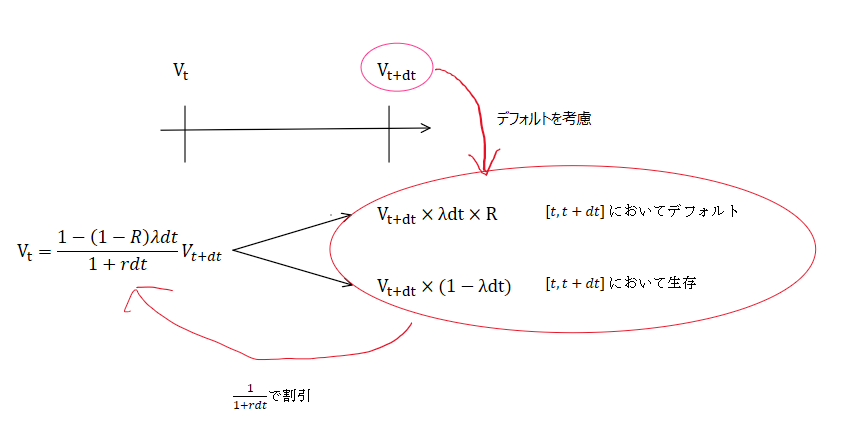

$dt$は微小であり $\frac{1}{1+r dt}\simeq 1 - rdt$ となるので


$$V_t = \frac{1-(1-R)\lambda dt}{1+rdt} V_{t+dt} \simeq (1-(1-R)\lambda dt)(1 - r dt)V_{t+dt} \simeq (1 - (r + (1-R)\lambda) dt ) V_{t+dt}$$


となり、整理すると以下の微分方程式が得られる。


$$\frac{V_{t+dt} - V_t}{V_{t+dt}} = (r+(1-R)\lambda)dt$$


これより、 $T>t$とすると $\lambda, R$は定数なので

 
$$V_T = V_t {\rm e}^{\int_t^T r_u {\rm d}u+(1-R)\lambda(T-t)}$$


となる。よって、時点ｔからみると $V_T,\int_t^T r_u {\rm d}u$は確率変数であるので


$$V_t = \mathbb{E}_t\left[ {\rm e}^{-\int_t^T r_u {\rm d}u - (1-R)\lambda (T-t)} V_T \right]$$


となる。この式は無リスク金利にクレジットスプレッドを加算して割引くことを意味している。 $(1-R)\lambda$がクレジットスプレッドに相当する。

割引債の場合は $V_T = 1$であるので


$$D(t,T) = \mathbb{E}_t\left[{\rm e}^{-\int_t^T r_s {\rm d} s} \right] {\rm e}^{-(1-R)\lambda (T-t)} = DF(t,T)  {\rm e}^{-(1-R)\lambda (T-t)}$$


となる。

**実装例**

デフォルトを考慮する時価での清算の場合をシミュレーションで評価するには、 金利パス生成して $\mathbb{E}_t\left[{\rm e}^{-\int_t^T r_s {\rm d} s} \right]$を評価するだけであるのでシミュレーションコードは割愛する。

ここでは、額面で清算、デフォルトを考慮しない時価で清算、デフォルトを考慮する時価で清算の３つ方法を同じパラメータで評価（数値積分・解析解）して比較する。

clear; 
% Vasicek model パラメータ
t0 = 0.0;
r0 = 0.0;
tht = 0.01; 
kappa = 0.1; 
sig = 0.005; 

% デフォルト関連パラメータ
lamb = 0.01;
rec = 0.4; 

% 満期
T = 10.0;

% デフォルトを考慮しない割引債価格
dfFun = @(rt,t,T) calcVasicekDF(rt,t,T,tht,kappa,sig);

% 額面清算
% 被積分関数
intfun = @(s) dfFun(r0,t0,s).*exp(-lamb*(s-t0));
%数値積分解
dfFaceValue = rec*lamb*integral(intfun,t0,T) + exp(-lamb*(T-t0))*dfFun(r0,t0,T);

% 無リスク時価で清算
dfRiskFree = dfFun(r0,t0,T).*(1-(1-rec)*(1-exp(-lamb*(T-t0))));

% デフォルトリスク込み時価で清算
dfDefaultRisk = dfFun(r0,t0,T).*exp(-(1-rec)*lamb*(T-t0));

% 結果の表示
disp(table(dfFaceValue,dfRiskFree,dfDefaultRisk));

    dfFaceValue    dfRiskFree    dfDefaultRisk
    ___________    __________    _____________

      0.66133       0.65405         0.65326   



### 2. CVAの評価

CVAは取引相手のデフォルトにより被る損失の期待値である。デフォルトを考慮する割引債価格での損失の期待値は $1-R$が損失率になるので、デフォルト時点での清算価格を $P_t$とすると


$$CVA(t,T) = (1-R)\lambda \mathbb{E}_t \left[\int_t^T {\rm e}^{-\int_t^s r_u {\rm d} u} P_s {\rm e}^{-\lambda (s-t)} {\rm d} s \right]$$


と表される。デフォルトを考慮した価格に代入して整理すると


$$D(t,T) = \lambda R \mathbb{E}_t \left[ \int_t^T {\rm e}^{-\int_t^s r_u {\rm d}u} P_s {\rm e}^{-\lambda(s-t)} {\rm d} s \right] + {\rm e}^{-\lambda  (T-t)} \mathbb{E}_t \left[ {\rm e}^{-\int_t^T r_s {\rm d} s} P_T \right] \\ = \lambda \mathbb{E}_t \left[ \int_t^T {\rm e}^{-\int_t^s r_u {\rm d}u} P_s {\rm e}^{-\lambda(s-t)} {\rm d} s \right] + {\rm e}^{-\lambda  (T-t)} \mathbb{E}_t \left[ {\rm e}^{-\int_t^T r_s {\rm d}s} P_T \right] - CVA(t,T)$$


となる。最後の式の最初に2項はデフォルトによる損失がない（デフォルト時点で100%回収される）場合の価格である。そこから期待損失額であるCVAを引くとデフォルトを考慮した価格となる。具体的な計算は清算価格の計算方法により異なるが、計算方法はデフォルトを考慮する割引債価格で示した方法とほぼ同じである。

割引債のような発行体のデフォルトリスクを考慮する有価証券の評価では、有価証券の保有者は発行体がデフォルトすれば必ず損失が発生する。しかし、フォワード取引やスワップ取引のようなデリバティブでは、取引相手のデフォルト時点で勝っている（時価が自分にとって正である）ときには損失が発生するが、負けている（時価が自分にとって負）のときには時価で清算（時価そのもの）するので価値が変わることがない。

つまり、取引相手のデフォルト時点で時価が正（ポジティブ エクスポージャーという）の場合にのみ損失率に応じて損失が発生する。よって、期待損失であるCVAはデフォルト時点での清算額を $P_t$とすると


$$CVA(t) = (1-R)\lambda \mathbb{E}_t \left[\int_t^T {\rm e}^{-\int_t^s r_u {\rm d} u} \max\left( P_s, 0 \right) {\rm e}^{-\lambda (s-t)} {\rm d} s \right]$$


となる。なお、デリバティブの中でもオプションを保有しているとき（常に時価は正）は $\max(P_s,0) = P_s$であり、オプションを売っているとき（常に時価は負）は $\max(P_s,0) = 0$(CVA = 0 )となることに注意する。

CVAは式からわかるようにデフォルト時点の清算価格に対する行使価格ゼロのコールオプション価格である。

デフォルトを考慮した割引債価格の評価と同様にデフォルト時の清算価格の決め方で価格評価の方法がかわる。デリバティブの場合は額面で清算することはあまりない（商品性に依存するが）ので、デフォルトを考慮しない時価で清算する、デフォルトを考慮した時価で清算する方法の2種類が考えられる。デフォルトを考慮した時価で清算する方法では、将来時点でのCVAを計算する必要があり計算負荷が大きいため、実務的には「デフォルトを考慮しない時価で清算する」とすることが多い。

なお、実際の計算ではCVAの式を次のように変形する。


$$CVA(t) = (1-R)\lambda \mathbb{E}_t \left[\int_t^T {\rm e}^{-\int_t^s r_u {\rm d} u} \max\left( P_s, 0 \right) {\rm e}^{-\lambda (s-t)} {\rm d} s \right] \\  = (1-R)\lambda \mathbb{E}_t \left[\int_t^T {\rm e}^{-\int_t^s r_u {\rm d} u} \mathbb{E}_s \left[ \max\left( P_s, 0 \right) \right] {\rm e}^{-\lambda (s-t)} {\rm d} s \right] \\ = (1-R)\lambda \mathbb{E}_t \left[\int_t^T {\rm e}^{-\int_t^s r_u {\rm d} u} EPE_s {\rm e}^{-\lambda (s-t)} {\rm d} s \right]$$


$EPE_s = \mathbb{E}_s \left[ \max \left(P_s, 0\right)\right]$は時点 $s$での時価が正の期待値(Exepcted Positive Exposure)である。 $EPE_s$は将来時点での条件付期待値評価であるので解析解が利用できない場合にはLSMなどで算出する必要がある。

### 例：金利フォワードのCVA

金利フォワードは満期時点 $T$で期間 $T_f$での適用金利を予め定める取引である。予め定める適用金利を $K$とすると金利フォワードの時点 $t$での価値は、簡単のために想定元本を１とすると、


$$V_t = \mathbb{E}_t\left[{\rm e}^{-\int_t^{T+T_f} r_s {\rm d} s} \left(R(T,T+T_f) - K \right) \right] \\ R(T,T+T_f) = -\frac{1}{T_f} \log DF(T,T + T_f )$$


となる。よって、この取引でのCVA計算は $EPE_s = \max(V_s,0)$とすればよい。

数値計算のためにCVAの式を変形する。


$$CVA(t) = (1-R)\lambda \int_t^T \mathbb{E}_t \left[ {\rm e}^{-\int_t^s r_u {\rm d}u} EPE_s {\rm e}^{-\lambda (s-t)} \right] {\rm d}s = (1-R)\lambda \int_t^T f(t,s) {\rm d} s \\ f(t,s) = \mathbb{E}_t \left[ {\rm e}^{-\int_t^s r_u {\rm d}u} EPE_s {\rm e}^{-\lambda (s-t)} \right]$$


これより離散時間近似により数値積分を行えばよいことがわかる。

**実装例**

金利モデルにVasicekを用いて、パラメータは割引債評価の例と同じとする。フォワード金利の条件は満期5年(T=5), 金利期間は半年( $T_f = 0.5$)とする。

ストライク金利はフォワード金利とする（ $K = -\frac{1}{T_f} \log \frac{DF(r_0,0,T+T_f)}{DF(r_0,0,T)}$）

シミュレーションで $EPE_s = \max(V_s,0)$を評価するときはLSMを用いる。LSMでの近似式は以下のようにする(違う関数形でもよい）。


$$V_s = \alpha_ 0 + \alpha_1 x_s + \alpha_2 x_s^2 + \cdots  \\ x_s =  -\frac{1}{T_f} \log \frac{DF(r_s,s,T+T_f)}{DF(r_s,s,T)}$$


LSMにおいて回帰結果は $\max(V_s,0)$の判定のみに用いる場合と、 $V_s$の値に用いる場合の2種類で行う。アメリカンオプションと違い最適行使判断をしていないので、判定のみに使う場合が

下方バイアスを持つわけではない。値を使う場合は $\max$の期待値計算であることから上方バイアスを持つことになる。

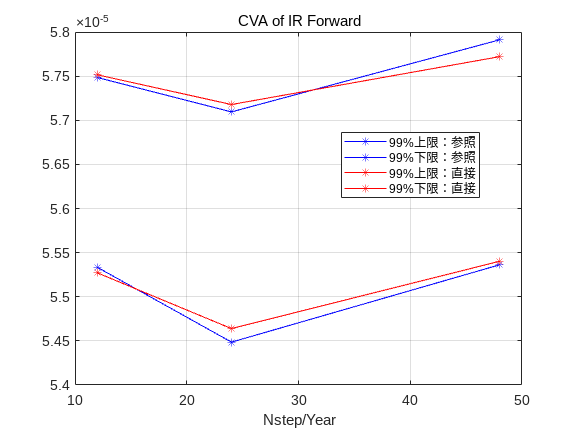

clear; 
% Vasicek model パラメータ
t0 = 0.0;
r0 = 0.0;
tht = 0.01; 
kappa = 0.1; 
sig = 0.005; 

% デフォルト関連パラメータ
lamb = 0.01;
rec = 0.4; 

% 満期と金利期間
T = 5.0;
Tf = 0.5; 

% デフォルトを考慮しない割引債価格
dfFun = @(rt,t,T) calcVasicekDF(rt,t,T,tht,kappa,sig);

% ストライク金利（フォワードレート）
K = -1/Tf*log(dfFun(r0,t0,T+Tf)./dfFun(r0,t0,T));

% 満期でのペイオフ
payoffFun = @(rT,T,Tf,K) (-1/Tf.*log(dfFun(rT,T,T+Tf))-K).*dfFun(rT,T,T+Tf);

% 回帰計算用の関数設定
regFun = @(xt) [ones(size(xt,1),1),xt]; 

%シミュレーションでの評価
Nsim = 10000;
Nsteps = [12;24;48]; %　1年あたりの分割数

Nt = 10;
alp = 0.01;

lowers1 = zeros(size(Nsteps));
uppers1 = zeros(size(Nsteps));

lowers2 = zeros(size(Nsteps));
uppers2 = zeros(size(Nsteps));

for iloop = 1:size(Nsteps,1)
    Nstep = Nsteps(iloop);
    dt = 1/Nstep; 
    % dt stepでの標準偏差
    sigv = sig*sqrt((1-exp(-2*kappa*dt))/(2*kappa));
    vs1 = zeros(Nt,1);
    vs2 = zeros(Nt,1);
    for jloop = 1:Nt
        % dt stepでの増分 (T-t0)/dtはステップ数
        sigdw = sigv * randn(Nsim,(T-t0)/dt);
        % 金利パスの生成
        rs = zeros(Nsim,(T-t0)/dt+1);
        rs(:,1) = r0;
        for kloop = 1:(T-t0)/dt
            rs(:,kloop+1) = rs(:,kloop)*exp(-kappa*dt) + tht/kappa*(1-exp(-kappa*dt)) + sigdw(:,kloop);
        end
        Ts = t0:dt:T;
        % 金利パスごとの満期でのペイオフ
        matPayoff = payoffFun(rs(:,end),T,Tf,K);
        % LSMのよるEPE計算
        [epeRef,epeDir] = lsmEE(Ts,T,Tf,rs,matPayoff,dfFun,regFun);
        % LSMの結果を0より大きいかどうかの判定だけに用いる場合
        vs1(jloop) = (1-rec)*lamb*trapz(Ts,epeRef.*exp(-lamb*Ts),2);
        % LSMの結果を値として用いる場合
        vs2(jloop) = (1-rec)*lamb*trapz(Ts,epeDir.*exp(-lamb*Ts),2);
    end
    rst = estConfidenceInterval(vs1,alp);
    lowers1(iloop) = rst.CILower;
    uppers1(iloop) = rst.CIUpper;

    rst = estConfidenceInterval(vs2,alp);
    lowers2(iloop) = rst.CILower;
    uppers2(iloop) = rst.CIUpper;
end

nfig = 3; 
figure(nfig);plot(Nsteps,[uppers1,lowers1],'b*-'); grid; title('CVA of IR Forward'); xlabel('Nstep/Year'); hold on; 
plot(Nsteps,[uppers2,lowers2],'r*-'); legend('99%上限：参照','99%下限：参照','99%上限：直接','99%下限：直接','Location','best'); hold off;

実際のCVA計算は取引相手とのポジション全体（ネッティングセット：デフォルト時に損益が合算される取引単位）を対象とする。そのため様々な商品を同時に計算することになるため多次元の問題となる。

## ローカル関数の定義

### LSMの実装：ポジティブエクスポージャー計算（判定のみ/値利用）

function [vepeRef,vepeDir] = lsmEE(Ts,T,Tf,rpath,matPayoff,dfFun,regFun)
    arguments
        Ts (1,:) {mustBeReal,mustBeNonnegative} % 時間グリッド
        T (1,1) {mustBeReal,mustBePositive} % 満期
        Tf (1,1) {mustBeReal,mustBePositive} %　金利計算期間
        rpath (:,:) {mustBeReal} % 金利パス
        matPayoff (:,1) {mustBeReal} %　満期でのペイオフ
        dfFun (1,1) function_handle % 割引債価格の解析解
        regFun (1,1) function_handle % 回帰関数の生成関数
    end

    % 回帰用説明変数の生成関数
    xs = @(rs,s) -1/Tf*log(dfFun(rs,s,T+Tf)./dfFun(rs,s,T));

    Nsim = size(rpath,1);
    
    % 金利パスの積分
    intr = cumtrapz(Ts,rpath,2);

    % 時点0でのデリバティブの価値
    v0 = max(mean(exp(-intr(:,end)).*matPayoff),0);  

    [vepeRef,vepeDir] = lsmEEImpl(rpath(:,2:end),intr(:,2:end),Ts(2:end),v0,v0);

    % EPE計算の本体
    function [repeRef,repeDir] = lsmEEImpl(rs,intr,ts,epeRef,epeDir)
        if isempty(rs) % 最終時点の確認
            repeRef = epeRef;
            repeDir = epeDir; 
            return;
        else
            % 回帰推定
            xt = xs(rs(:,1),ts(1));
            X = regFun(xt);
            Vp = matPayoff.*exp(-intr(:,end) + intr(:,1));
            coeff = (X'*X)\(X'*Vp);

            % 回帰結果による推定値
            Vplsm = X*coeff; 
            id = find(Vplsm > 0); % 推定値で in the moneyとなるパスの番号
            % 回帰結果は参照
            epeReftmp = zeros(Nsim,1);
            epeReftmp(id) = Vp(id);
            % 回帰結果を利用
            epeDirtmp = zeros(Nsim,1);
            epeDirtmp(id) = Vplsm(id);
            % 再帰計算
            [repeRef,repeDir] = lsmEEImpl(rs(:,2:end),intr(:,2:end),ts(2:end),[epeRef,mean(epeReftmp)],[epeDir,mean(epeDirtmp)]);
        end
    end
end

### Vasicekモデルの割引債価格の解析解

function df = calcVasicekDF(rt,t,T,tht,kappa,sigr)
    arguments
        rt (:,:) {mustBeReal}
        t (:,:) {mustBeReal,mustBeNonnegative}
        T (:,:) {mustBeReal,mustBePositive}
        tht (1,1) {mustBeReal}
        kappa (1,1) {mustBeReal,mustBeNonnegative}
        sigr (1,1) {mustBeReal,mustBePositive}
    end
    Tt = T-t;
    BtT = @(k) (1-exp(-k*Tt))/k;
    AtT = exp(-tht/kappa*(Tt-BtT(kappa))+1/2*(sigr/kappa)^2*(Tt-2*BtT(kappa)+BtT(2*kappa)));
    df = AtT.*exp(-rt.*BtT(kappa));
end